This script looks at example 8.9 from your book and shows code that demonstrates how to compute mu and the singular values and plot them.

Start by building the plant, controller, and uncertainty weight for the 2x2 system.

 tau = 75;
 G=tf([0 1],[tau 1])*[-87.8 1.4;-108.2 -1.4]; % Plant 
 K=tf([tau 1],[1 1e-6])*[-0.0015 0; 0 -0.075]; % Controller 

Now deal with the uncertainty.  Because the uncertainty here is complex, we'll use the *ultidyn* command to build an arbitrary LTI system.  I'll build 2, one for each input, and put the uncertainty together into a weight.

 wI=0.2*tf([5 1],[0.5 1]); % Input uncertainty 
 D1 = ultidyn('D1',[1 1]);
 D2 = ultidyn('D2',[1 1]);
 WI = [wI 0;0 wI];
 %The below are for robust analysis without computing mu
 WI_unc = [D1*wI 0;0 D2*wI];
 Gp = G*(eye(2)+WI_unc);

We have seen that for multiplicative input uncertainty $M = K(I+GK)^{-1}GW_I = KSGW_I$

M = K*(eye(2)-feedback(G*K,eye(2)))*G*WI;

Now we'll use the command *mussv* to compute the structured singular value.  Use of this command is complicated by 1.)  It wants a plant of type FRD, and 2.)  It wants to know the block structure of Delta.  See the help for details on that.

w = logspace(-3,2,101);  %Frequency vector
bounds= mussv(frd(M,w),[1 1;1 1]);  %This makes two full diagonal blocks

Points completed: 101/101


Bounds returns the upper and lower bounds on mu as a function of frequency.  To get the critical value of mu from the data:

mu = getPeakGain(bounds(1,1))  %The 1,1 entry is the UPPER bound

mu = 0.3684

gam = norm(M,'inf')

gam = 9.6159

mu is less than 1, and hence we have robust stability.  However, for unstructured uncertainty we would be in trouble!  We can graph mu over frequency if we care to see at what frequency things go bad.  Before we do that, let's compute the singular values of M to show the relationship between structured and unstructured singular values.

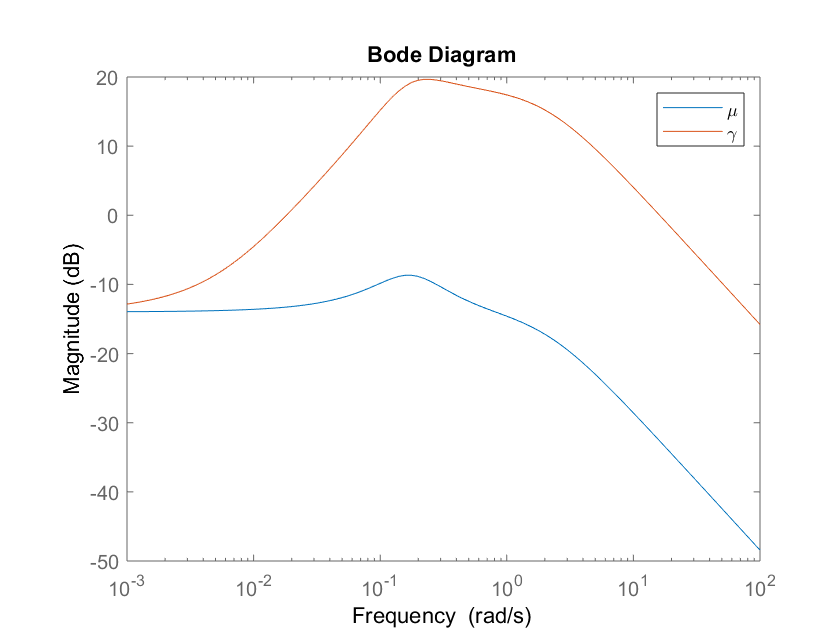

sig = sigma(M,w);  %Command to compute singular values over frequency
sigfrd = frd(sig(1,:),w);
bodemag(bounds(1,1),sigfrd(1,1))
legend('\mu','\gamma')

Clearly for this simple 2x2 system the fact that the uncertainty has structure (is diagonal) matters a great deal.

**robstab**

Computation of mu was a little painful.  Thankfully, leveraging the uncertain systems structure, we can check robust stability with much less work.  Let's start by finding the uncertain sensitivity function.

S = inv(eye(2)+Gp*K);

Now we go straight to the analysis.

[STABMARG,WCU] = robstab(S);

The returns of this command are weird, effectively giving 1/mu as the main output.

mu = 1/STABMARG.LowerBound

mu = 0.3699

Obviously the same answer, and we came by it through much less pain.